# Introduction

- Problem definition – predict school performance score (SPGScore)

- decision tree and svmwith cv and grid search

- Ensemble Learners: TreeBaggerand Boosting

- Predictor Importance and feature reduction

- Feed forward neural network to predict SPGScorewith best predictors

- Compare various neural network architectures

# Loading the data

clear; clc; close all;
% load the data
load ml_data

% Remove the SPGrade variable : 
ml_data(:,'SPGGrade') = [];

% Store the target variable
ml_data_output = ml_data.SPGScore;

% Remove the class variable : SPGScore;
ml_data(:,'SPGScore') = [];

% Scale the data; Normalize it; use zscore
ml_data{:,:} = zscore(ml_data{:,:});

% Split the data into training and test sets
% Create the cvpartition variable
pt = cvpartition(ml_data_output, 'HoldOut', 0.25);


% Create the training and test tables
nc_train_input = ml_data(training(pt), :);
nc_train_output = ml_data_output(training(pt), :);

nc_test_input = ml_data(test(pt), :);
nc_test_output = ml_data_output(test(pt), :);

% set random seed.
rng(1);

# Decision Tree Regression (fitrtree)

Fitrtree 

Predict

Calculate error

Calculate R-square

Plot Error Histogram

Plot Scatter Plot

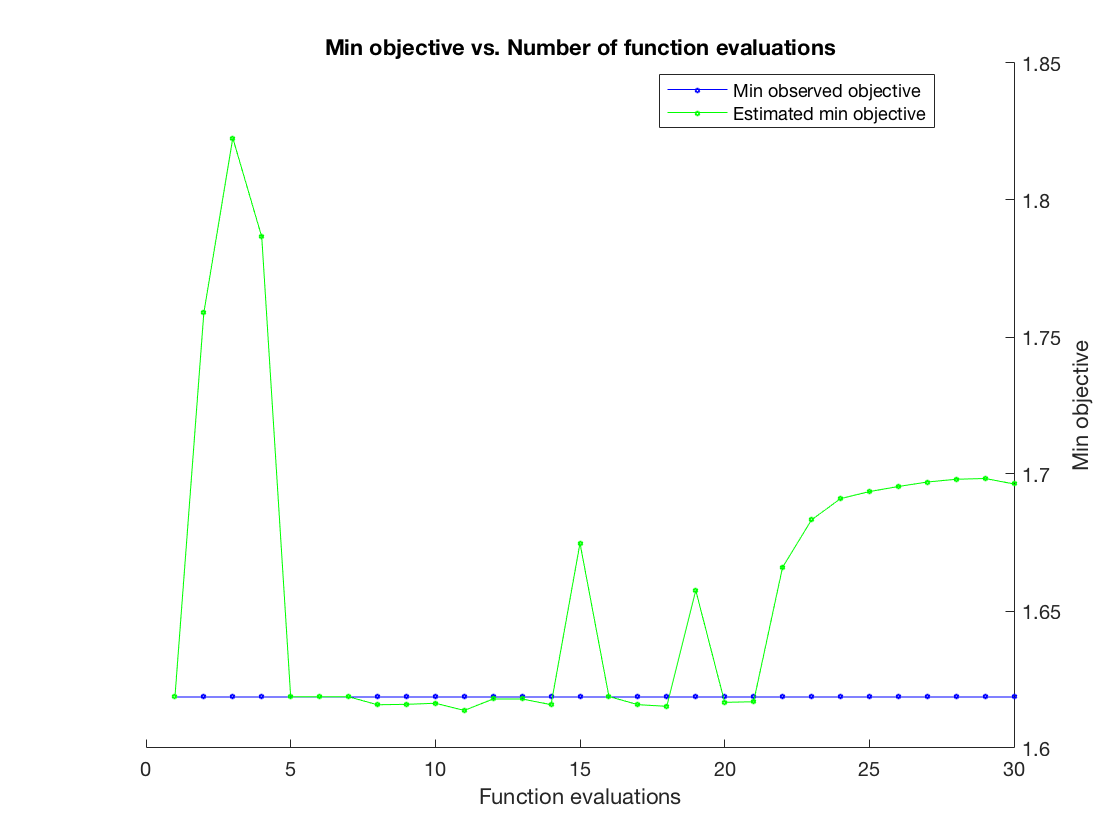

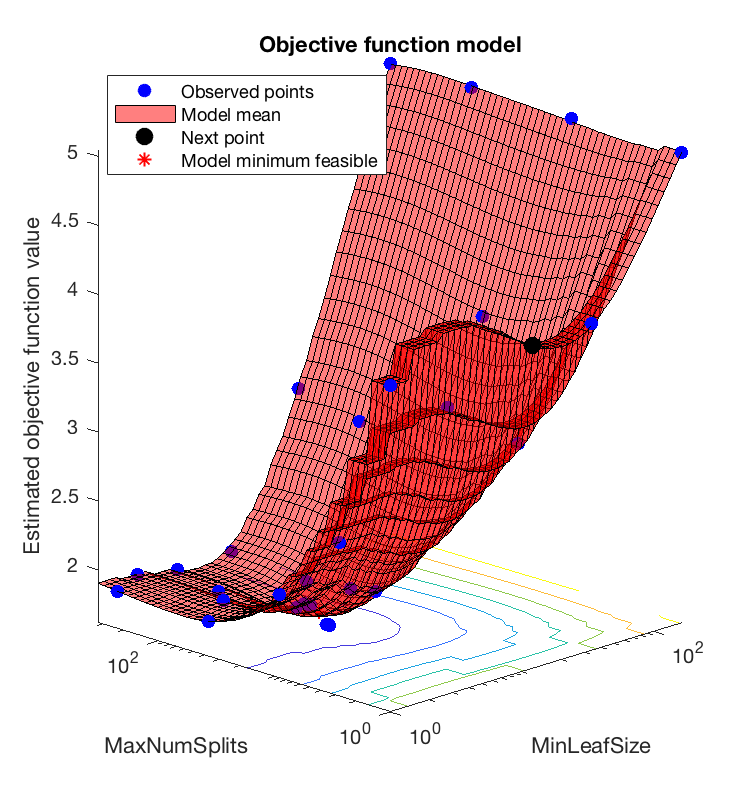

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize | MaxNumSplits |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      1.6186 |      0.6223 |      1.6186 |      1.6186 |            7 |           32 |
|    2 | Accept |      3.6373 |     0.30916 |      1.6186 |      1.7589 |           64 |           18 |
|    3 | Accept |       3.546 |      0.2202 |      1.6186 |      1.8226 |            5 |            2 |
|    4 | Accept |      1.8832 |     0.53536 |      1.6186 |      1.7866 |            1 |          223 |
|    5 | Accept |      1.6186 |     0.30534 |      1.6186 |      1.6187 |            7 |           30 |
|    6 | Accept |       3.032 |     0.17695 |      1.6186 |     

Mdl_rtree =   RegressionTree
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 330
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


Mdl_rtree = fitrtree(nc_train_input,nc_train_output,'OptimizeHyperparameters',{'MinLeafSize', 'MaxNumSplits'},...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))

% predict
outputs_rtree_train=predict(Mdl_rtree,nc_train_input);
outputs_rtree_test=predict(Mdl_rtree,nc_test_input);

%--------------------------------------------------------------------------
% calculate the mean square error (MSE) of the test points
mse_train=sum((outputs_rtree_train - nc_train_output).^2)/length(nc_train_output);
mse_test=sum((outputs_rtree_test - nc_test_output).^2)/length(nc_test_output);

%--------------------------------------------------------------------------
% calculate the correlation coefficients for the training and test data 
% sets with the associated linear fits hint: check out the function corrcoef
R_train = corrcoef(outputs_rtree_train,nc_train_output);
R_test = corrcoef(outputs_rtree_test,nc_test_output);
r_train=R_train(1,2);
r_test=R_test(1,2);

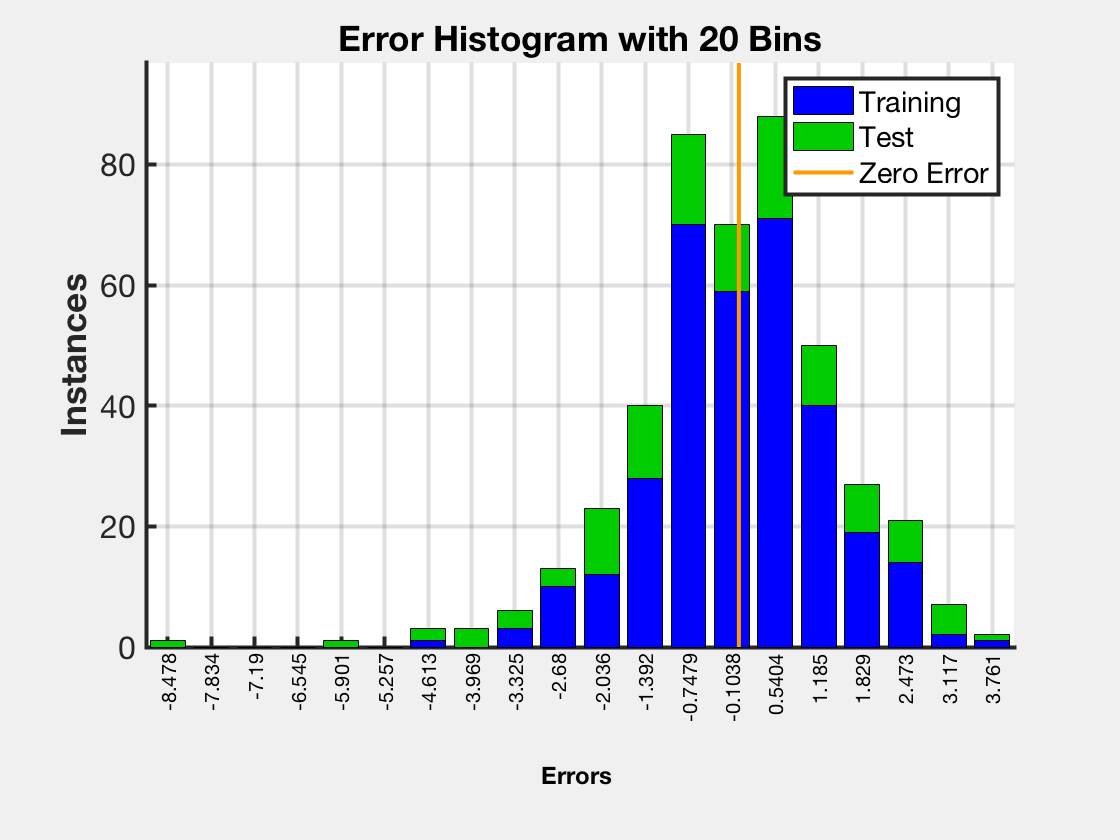

% plot error histogram
plotErrorHistogram(nc_train_output, outputs_rtree_train, nc_test_output, outputs_rtree_test)

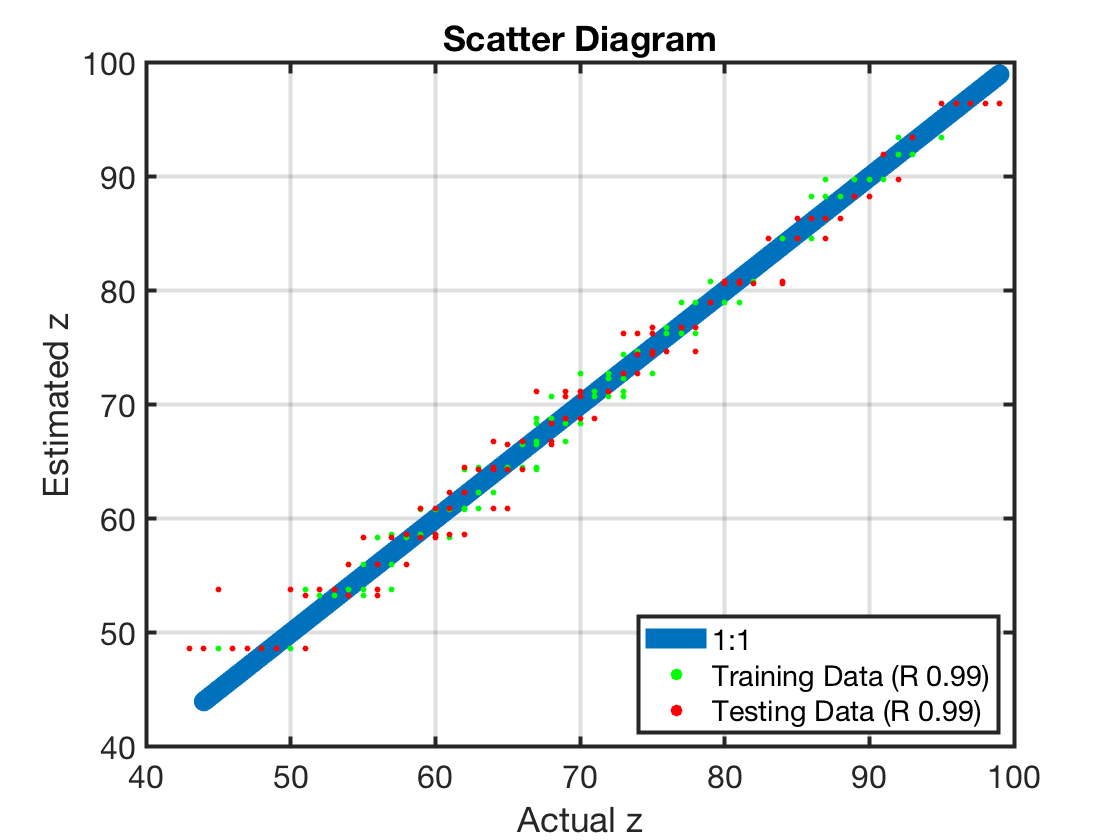

% plot scatter plot
plotScatterDiagram(nc_train_output, outputs_rtree_train, nc_test_output, outputs_rtree_test, r_train, r_test)

# `SVM (fitrlinear)`

`fitrlinear` efficiently trains linear regression models with high-dimensional, full or sparse predictor data. Available linear regression models include regularized support vector machines (SVM) and least-squares regression methods. `fitrlinear` minimizes the objective function using techniques that reduce computing time (e.g., stochastic gradient descent).

A high-dimensional data set includes many predictor variables. Although such a data set can consume a significant fraction of memory, it must fit in the MATLAB® Workspace. For low- through medium-dimensional predictor data sets, see [Alternatives for Lower-Dimensional Data](https://www.mathworks.com/help/stats/fitrlinear.html#mw_deb08507-aa77-4f31-a3c8-715abb45cb6c).

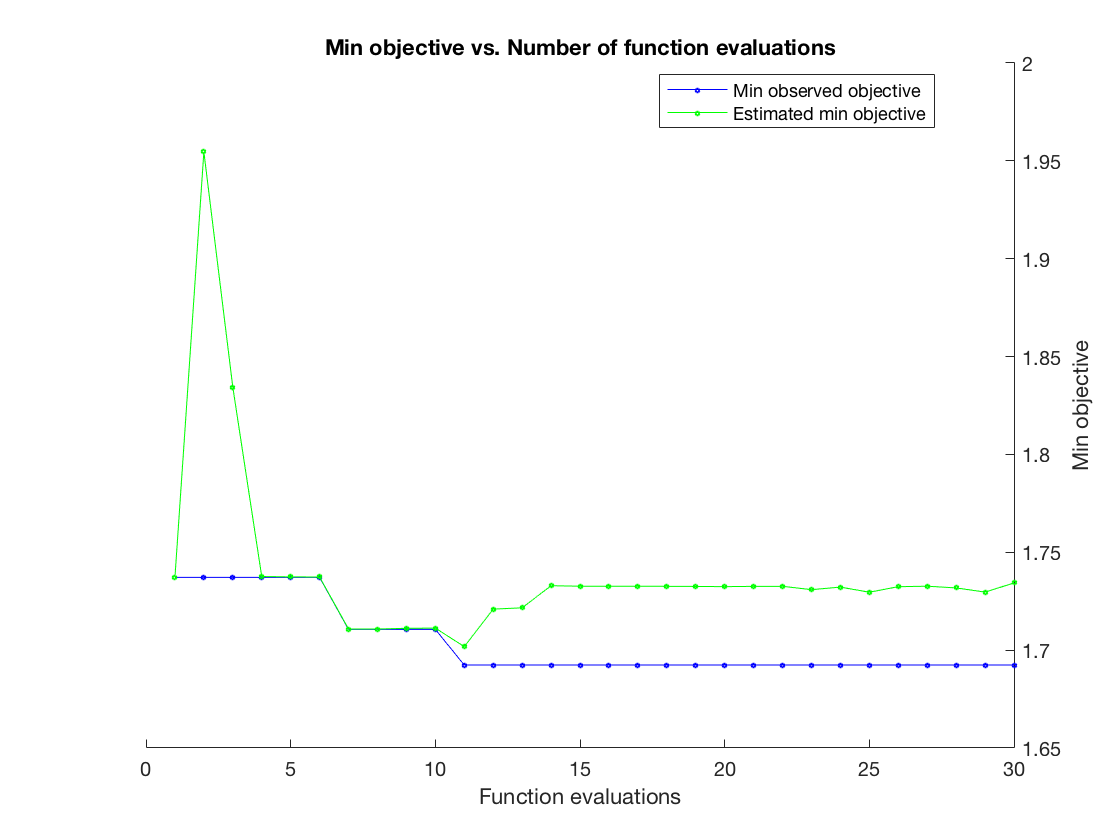

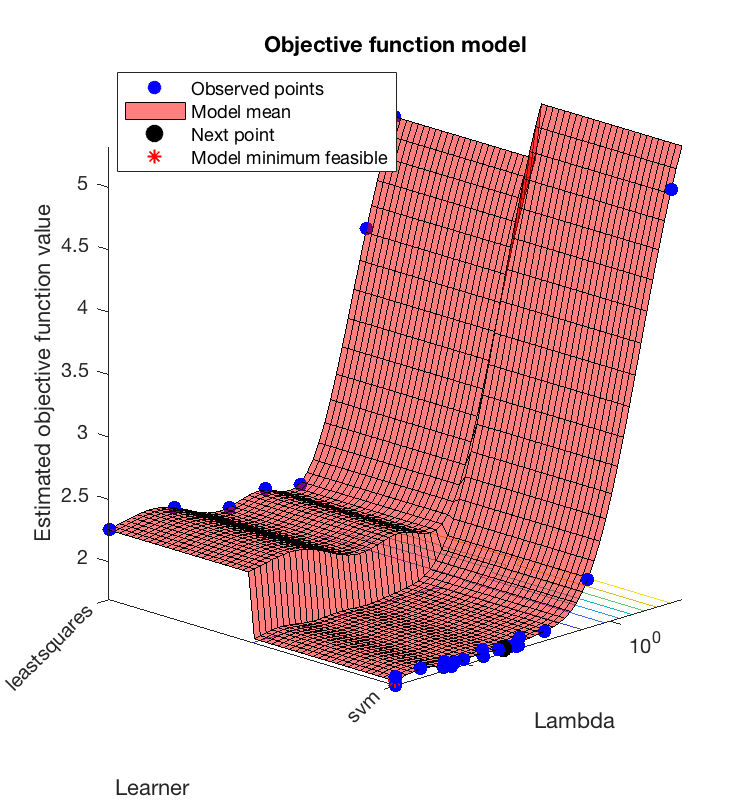

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      1.7372 |      2.2362 |      1.7372 |      1.7372 |   0.00012256 |          svm |
|    2 | Accept |      5.0085 |      0.3269 |      1.7372 |      1.9546 |       127.51 |          svm |
|    3 | Accept |      2.2564 |     0.38839 |      1.7372 |      1.8344 |   3.4291e-08 | leastsquares |
|    4 | Accept |      2.1398 |     0.29407 |      1.7372 |      1.7376 |   0.00051864 | leastsquares |
|    5 | Accept |      1.7407 |     0.30593 |      1.7372 |      1.7374 |   7.2114e-06 |          svm |
|    6 | Accept |      4.0463 |     0.25114 |      1.7372 |     

Mdl_svm =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [141×1 double]
                 Bias: 70.4889
               Lambda: 2.8670e-06
              Learner: 'svm'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 2.8670e-06
                 Objective: 0.1975
                 PassLimit: 10
                 NumPasses: 10
                BatchLimit: []
             NumIterations: 3300
              GradientNorm: NaN
         GradientTolerance: 0
      RelativeChangeInBeta: 0.0085
             BetaTolerance: 1.0000e-04
             DeltaGradient: 5.3138
    DeltaGradientTolerance: 0.1000
           TerminationCode: 0
         TerminationStatus: {'Iteration limit exceeded.'}
                     Alpha: [330×1 double]
                   History: []
                   FitTime: 0.0030
                    Solver: {'dual'}


HyperparameterOptimizationResults =   BayesianOptimization with properties:

                      ObjectiveFcn: @createObjFcn/theObjFcn
              VariableDescriptions: [3×1 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: 1.6924
                   XAtMinObjective: [1×2 table]
             MinEstimatedObjective: 1.7343
          XAtMinEstimatedObjective: [1×2 table]
           NumObjectiveEvaluations: 30
                  TotalElapsedTime: 90.1843
                         NextPoint: [1×2 table]
                            XTrace: [30×2 table]
                    ObjectiveTrace: [30×1 double]
                  ConstraintsTrace: []
                     UserDataTrace: {30×1 cell}
      ObjectiveEvaluationTimeTrace: [30×1 double]
                IterationTimeTrace: [30×1 double]
                        ErrorTrace: [30×1 double]
                  Feasibil

hyperopts = struct('AcquisitionFunctionName','expected-improvement-plus');
nc_train_input_matrix = nc_train_input{:,:};
[Mdl_svm,FitInfo,HyperparameterOptimizationResults] = fitrlinear(nc_train_input_matrix,nc_train_output,...
    'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',hyperopts)

% predict
outputs_svm_train=predict(Mdl_svm,nc_train_input_matrix);
nc_test_input_matrix = nc_test_input{:,:};
outputs_svm_test=predict(Mdl_svm,nc_test_input_matrix);

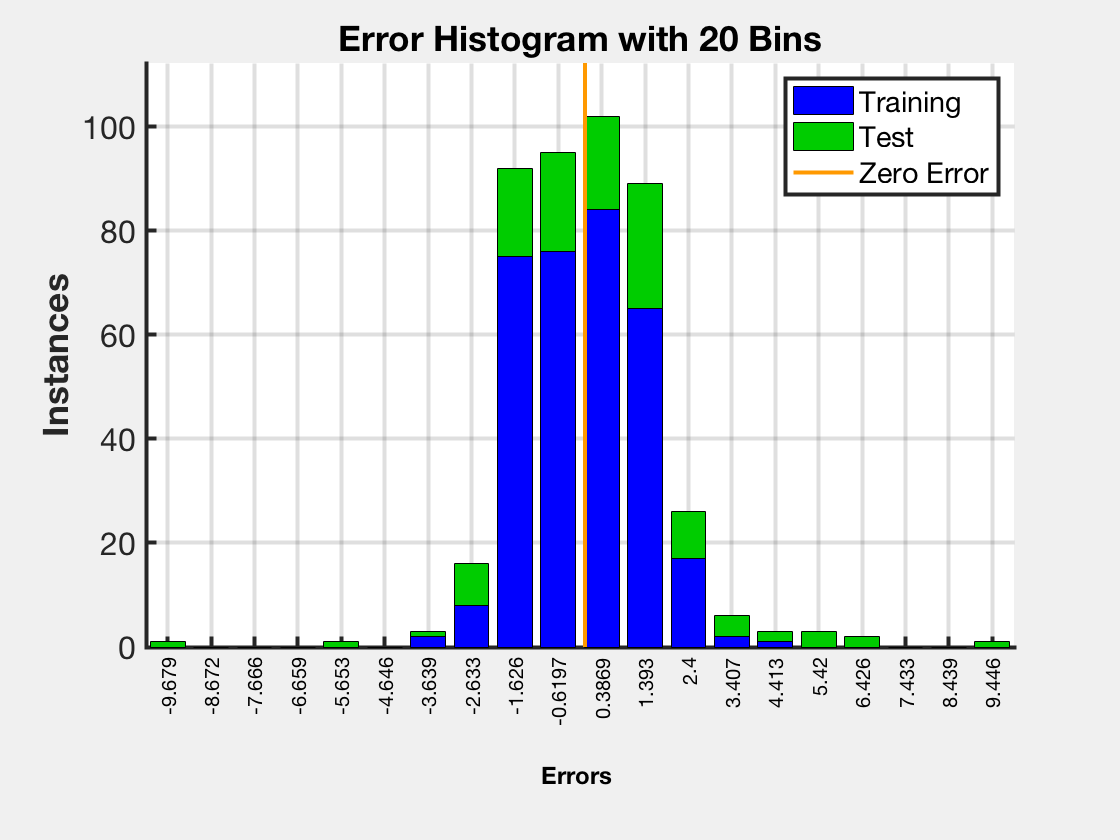

% plot error histogram
plotErrorHistogram(nc_train_output, outputs_svm_train, nc_test_output, outputs_svm_test)

%--------------------------------------------------------------------------
% calculate the mean square error (MSE) of the test points
mse_train=sum((outputs_svm_train - nc_train_output).^2)/length(nc_train_output);
mse_test=sum((outputs_svm_test - nc_test_output).^2)/length(nc_test_output);

%--------------------------------------------------------------------------
% calculate the correlation coefficients for the training and test data 
% sets with the associated linear fits hint: check out the function corrcoef
R_train = corrcoef(outputs_svm_train,nc_train_output);
R_test = corrcoef(outputs_svm_test,nc_test_output);
r_train=R_train(1,2);
r_test=R_test(1,2);

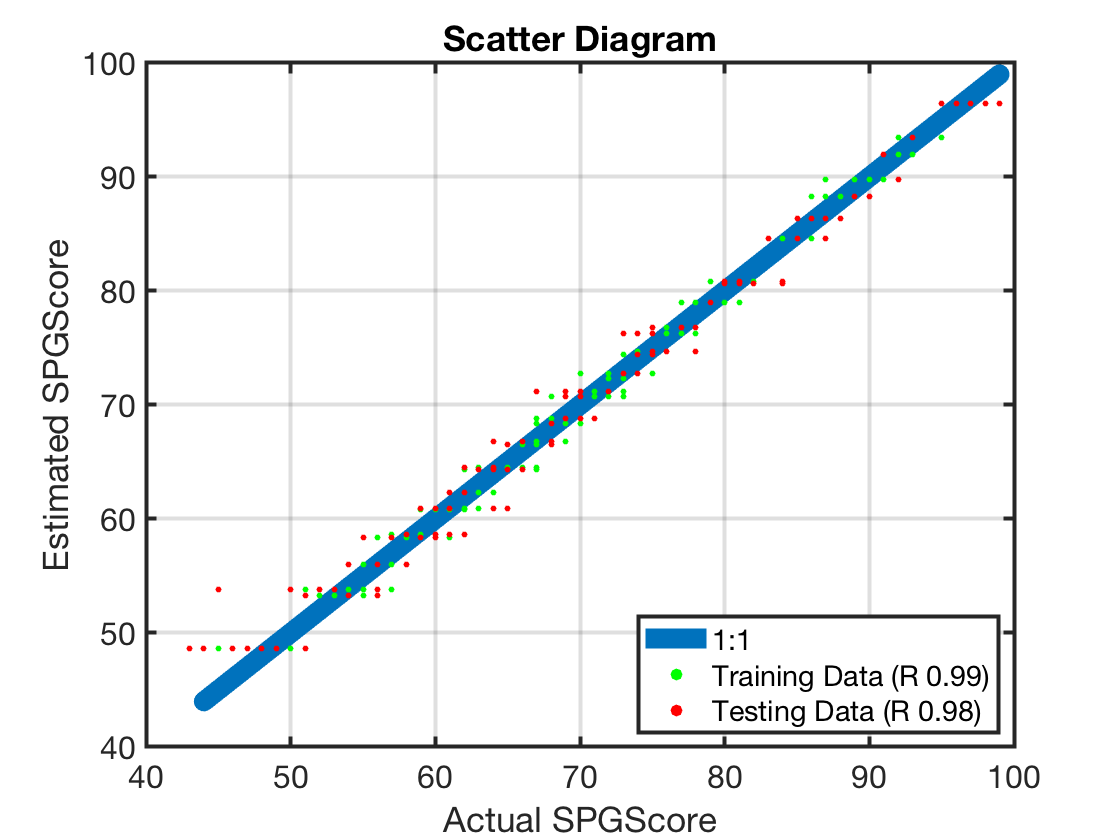


% plot scatter plot
plotScatterDiagram(nc_train_output, outputs_rtree_train, nc_test_output, outputs_rtree_test, r_train, r_test)

# TreeBagger Regression

Mdl_TB = TreeBagger(...
    100,nc_train_input,nc_train_output,...
    'Method','Regression',...
    'Surrogate','on',...
    'PredictorSelection','curvature',...
    'OOBPredictorImportance','on'...
    )

Mdl_TB =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:            [330x141]
                    Training Y:              [330x1]
                        Method:           regression
                 NumPredictors:                  141
         NumPredictorsToSample:                   47
                   MinLeafSize:                    5
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []

  Properties, Methods


% predict
outputs_tb_train=predict(Mdl_TB, nc_train_input);
outputs_tb_test=predict(Mdl_TB,nc_test_input);

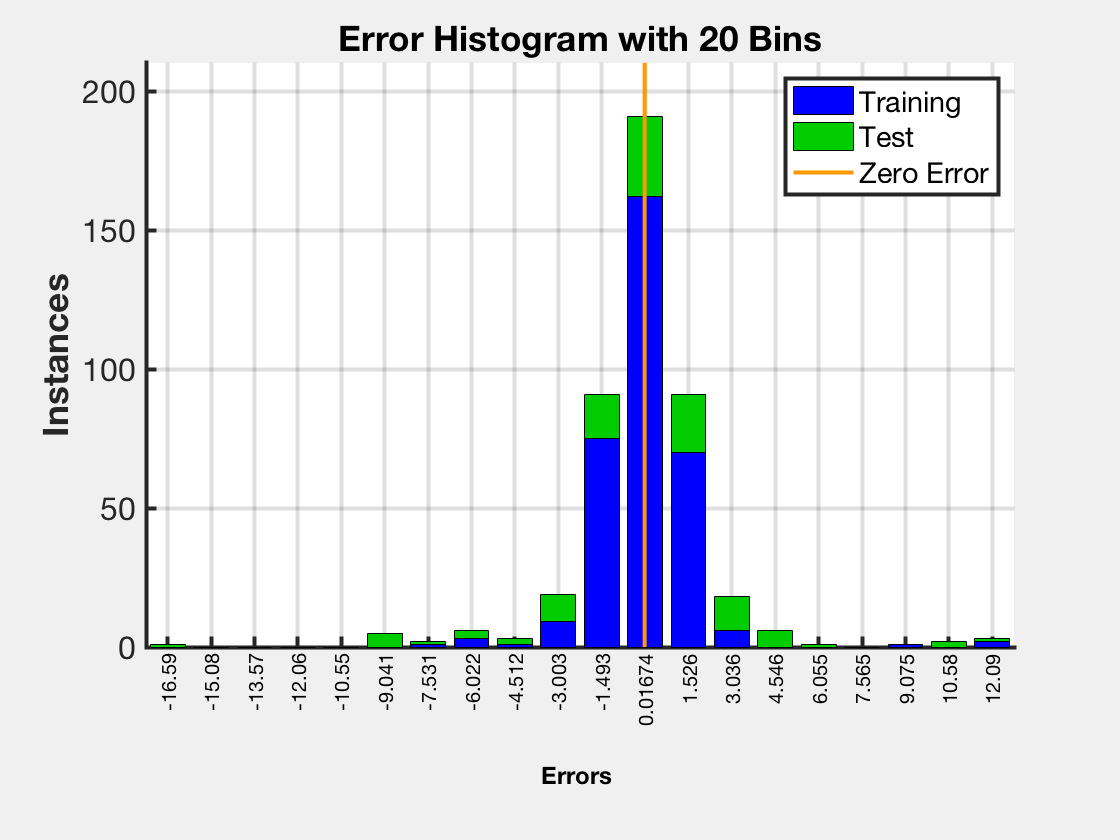

% plot error histogram
plotErrorHistogram(nc_train_output, outputs_tb_train, nc_test_output, outputs_tb_test)

%--------------------------------------------------------------------------
% calculate the mean square error (MSE) of the test points
mse_train=sum((outputs_tb_train - nc_train_output).^2)/length(nc_train_output);
mse_test=sum((outputs_tb_test - nc_test_output).^2)/length(nc_test_output);

%--------------------------------------------------------------------------
% calculate the correlation coefficients for the training and test data 
% sets with the associated linear fits hint: check out the function corrcoef
R_train = corrcoef(outputs_tb_train,nc_train_output);
R_test = corrcoef(outputs_tb_test,nc_test_output);
r_train=R_train(1,2);
r_test=R_test(1,2);

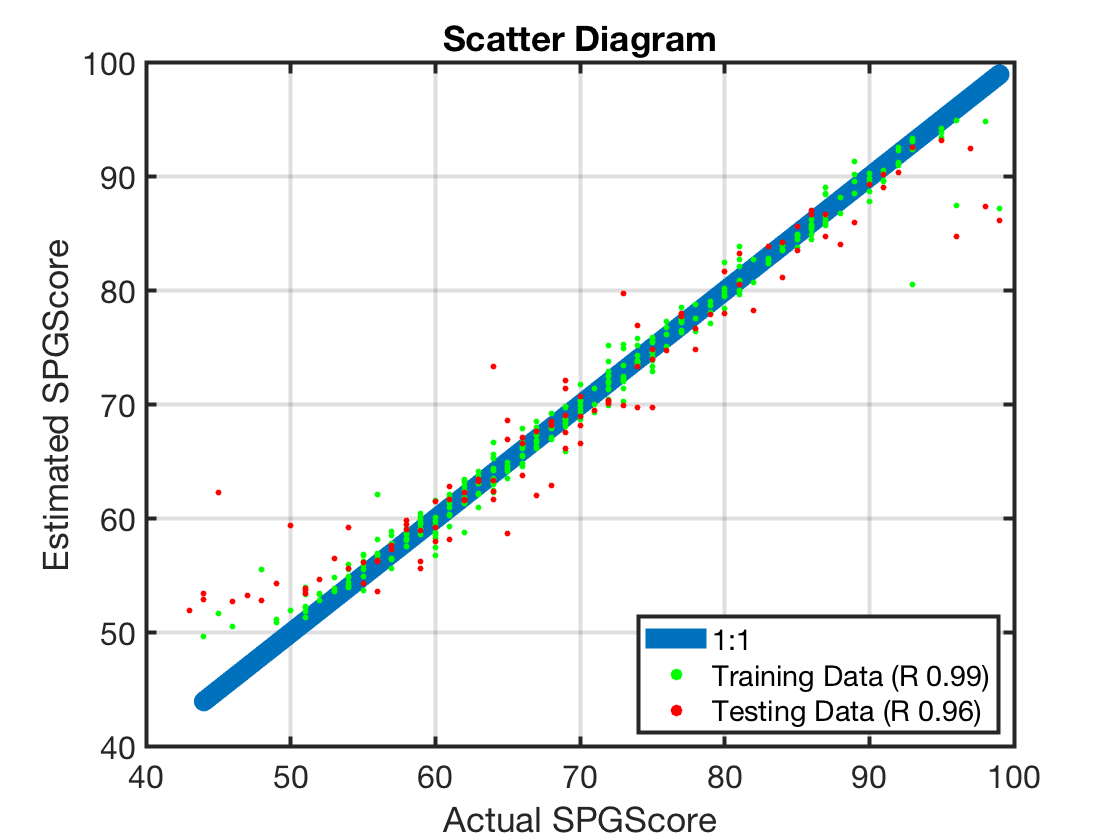

% plot scatter plot
plotScatterDiagram(nc_train_output, outputs_tb_train, nc_test_output, outputs_tb_test, r_train, r_test)

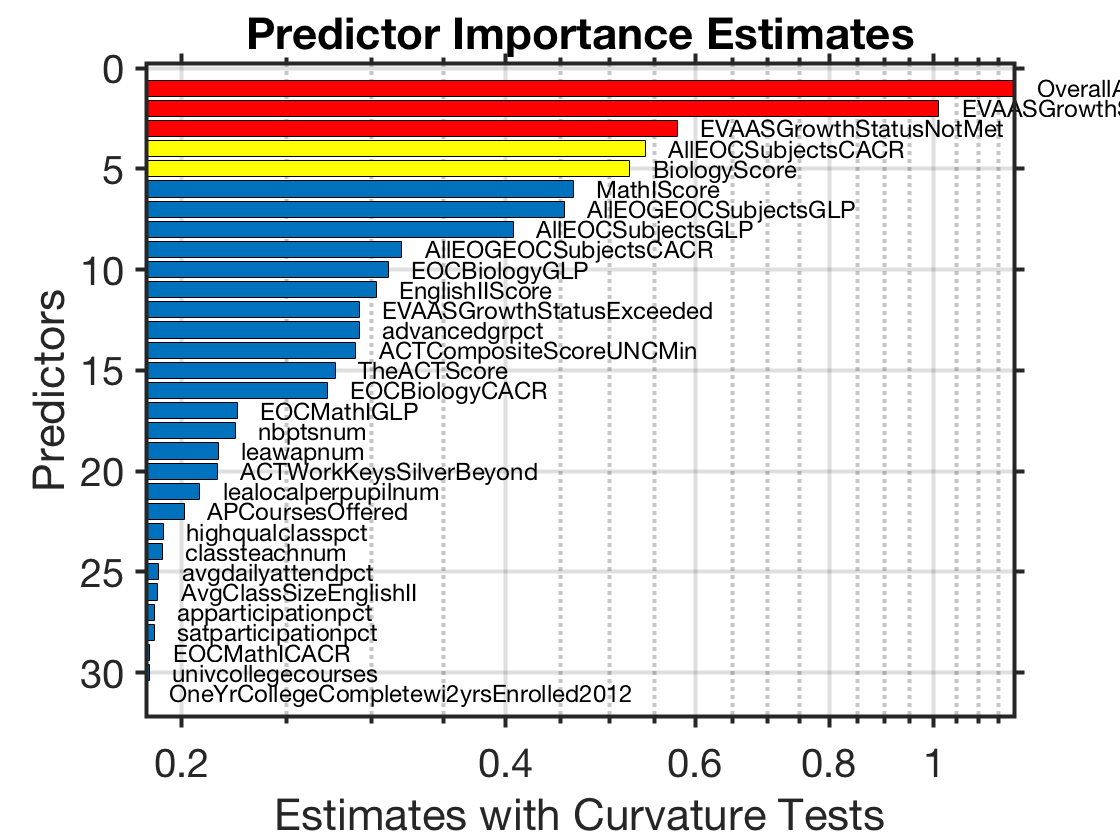

%--------------------------------------------------------------------------
% Estimate the predictor importance
imp=Mdl_TB.OOBPermutedPredictorDeltaError;
[sorted_imp,isorted_imp] = sort(imp,'descend');  

n = sum(imp>0);
if n  > 31
    n = 31;
end

%--------------------------------------------------------------------------
% Draw a horizontal bar chart showing the variables in descending order of
% importance. Hint: look up the function barh.
% Label each variable with its name. 
% Hints: (1) Look up the function text. (2) Variable names are held in 
% Mdl.PredictorNames
figure;barh(imp(isorted_imp(1:n)));hold on;grid on;
barh(imp(isorted_imp(1:5)),'y');barh(imp(isorted_imp(1:3)),'r');
title('Predictor Importance Estimates');
xlabel('Estimates with Curvature Tests');ylabel('Predictors');
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
ax = gca;ax.YDir='reverse';ax.XScale = 'log';

sorted_predictor_names = Mdl_TB.PredictorNames(isorted_imp(1:n));

% label the bars
for i=1:length(sorted_predictor_names)
   text(...
        1.05*imp(isorted_imp(i)),i,...
        strrep(sorted_predictor_names{i},'_',''),...
        'FontSize',12 ...
    )
end
print('-dpng','NC-full-input-importance.png');% save to an png file

for col=sorted_predictor_names
disp(col)
end

    'OverallAchievementScore'

    'EVAASGrowthScore'

    'EVAASGrowthStatus_NotMet'

    'All_EOC_Subjects_CACR'

    'BiologyScore'

    'MathIScore'

    'All_EOG_EOC_Subjects_GLP'

    'All_EOC_Subjects_GLP'

    'All_EOG_EOC_Subjects_CACR'

    'EOC_Biology_GLP'

    'EnglishIIScore'

    'EVAASGrowthStatus_Exceeded'

    'advance_dgr_pct'

    'ACT_Composite_Score_UNC_Min'

    'TheACTScore'

    'EOC_Biology_CACR'

    'EOC_Math_I_GLP'

    'nbpts_num'

    'lea_wap_num'

    'ACT_WorkKeys_Silver_Beyond'

    'lea_local_perpupil_num'

    'AP_Courses_Offered'

    'highqual_class_pct'

    'class_teach_num'

    'avg_daily_attend_pct'

    'Avg_Class_Size_EnglishII'

    'ap_participation_pct'

    'sat_participation_pct'

    'EOC_Math_I_CACR'

    'univ_college_courses'

    'One_Yr_College_Complete_wi_2_yrs_Enrolled_2012'



# TreeBagger Occum's Razor (Reduced Model)

% Model using the best predictors
nc_train_input_simpler = nc_train_input(:, isorted_imp(1:n));
nc_test_input_simpler = nc_test_input(:, isorted_imp(1:n));

% set random seed.
rng(1);

Mdl_TB_simpler = TreeBagger(...
    100,nc_train_input_simpler,nc_train_output,...
    'Method','Regression',...
    'Surrogate','on',...
    'PredictorSelection','curvature',...
    'OOBPredictorImportance','on'...
    )

Mdl_TB_simpler =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [330x31]
                    Training Y:              [330x1]
                        Method:           regression
                 NumPredictors:                   31
         NumPredictorsToSample:                   11
                   MinLeafSize:                    5
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []

  Properties, Methods


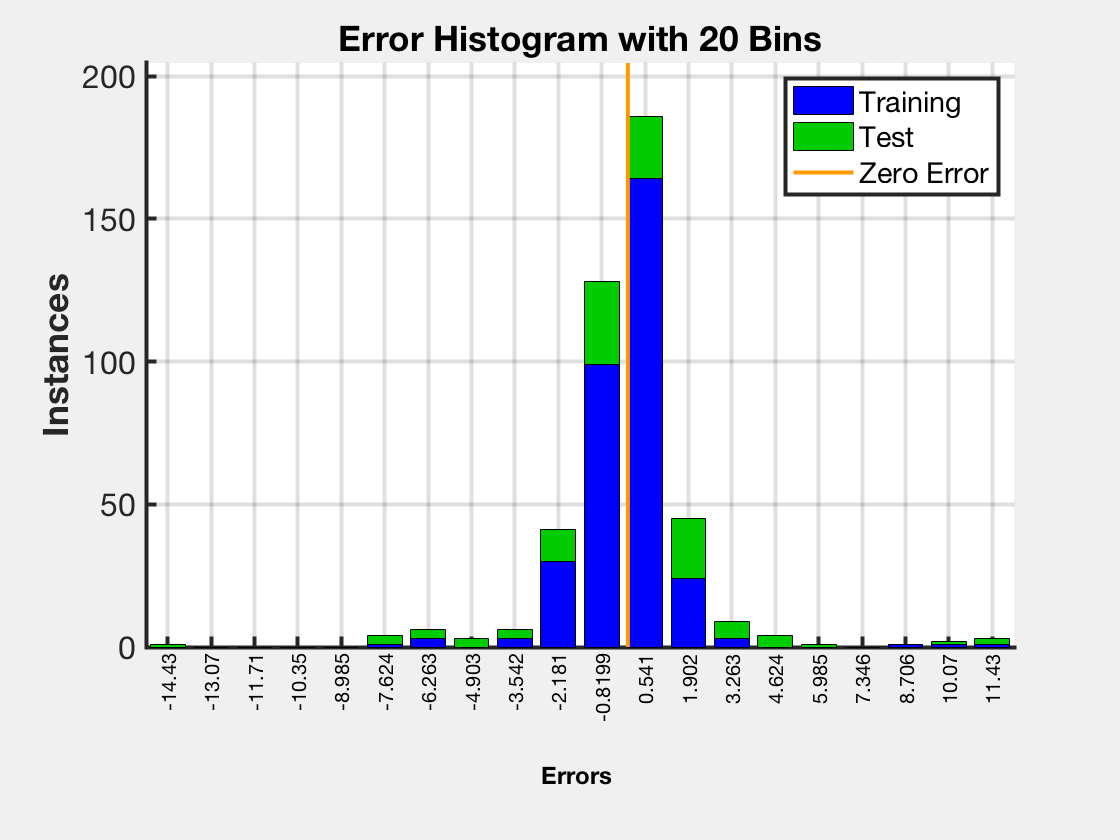

% predict
outputs_tb_train_simpler=predict(Mdl_TB_simpler, nc_train_input_simpler);
outputs_tb_test_simpler=predict(Mdl_TB_simpler,nc_test_input_simpler);
% plot error histogram
plotErrorHistogram(nc_train_output, outputs_tb_train_simpler, nc_test_output, outputs_tb_test_simpler)

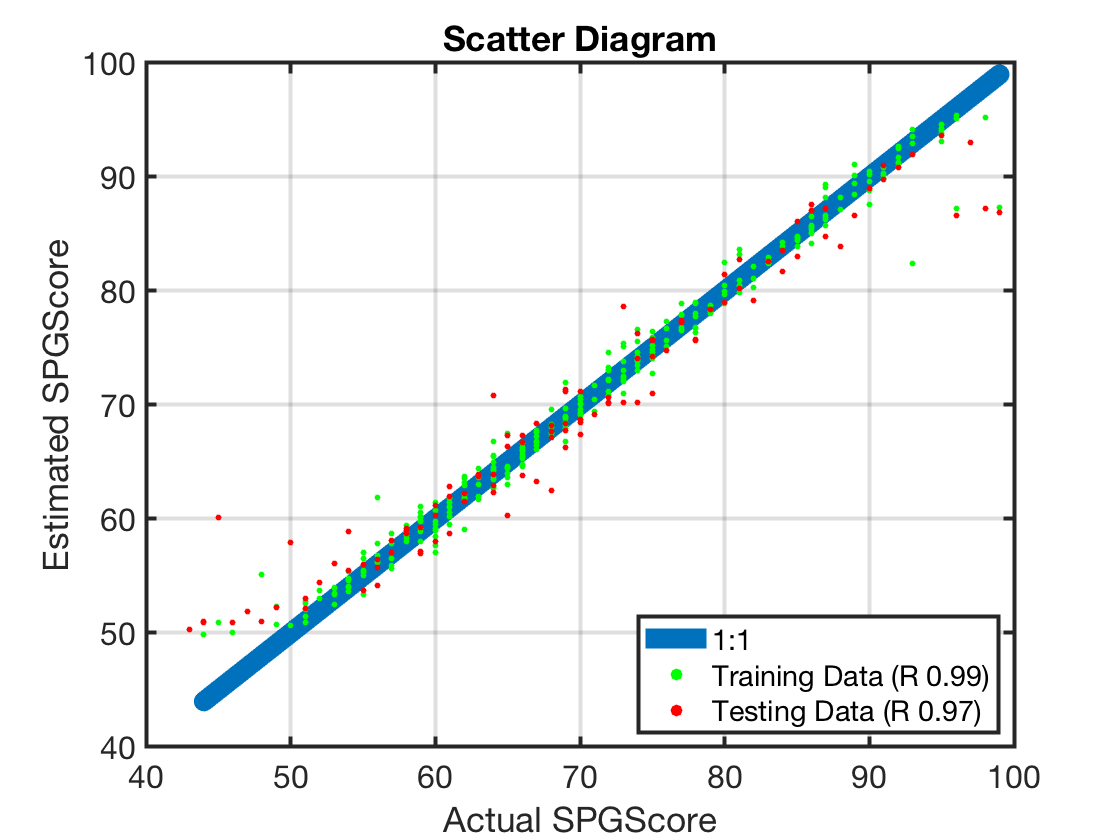

%--------------------------------------------------------------------------
% calculate the mean square error (MSE) of the test points
mse_train=sum((outputs_tb_train_simpler - nc_train_output).^2)/length(nc_train_output);
mse_test=sum((outputs_tb_test_simpler - nc_test_output).^2)/length(nc_test_output);

%--------------------------------------------------------------------------
% calculate the correlation coefficients for the training and test data 
% sets with the associated linear fits hint: check out the function corrcoef
R_train = corrcoef(outputs_tb_train_simpler,nc_train_output);
R_test = corrcoef(outputs_tb_test_simpler,nc_test_output);
r_train=R_train(1,2);
r_test=R_test(1,2);
% plot scatter plot
plotScatterDiagram(nc_train_output, outputs_tb_train_simpler, nc_test_output, outputs_tb_test_simpler, r_train, r_test)

# Ensemble Regression Models (Boosting)

Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
Copying objective function to workers...
Done copying objective function to workers.


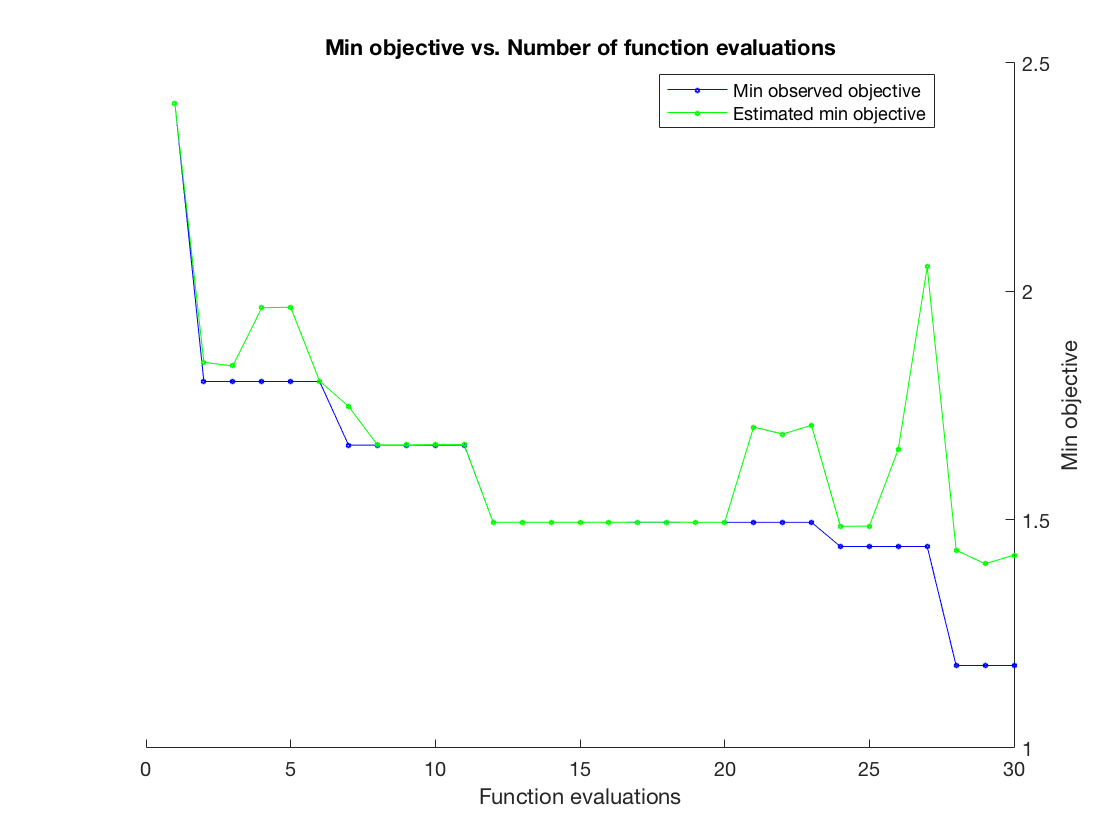

|===========================================================================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize | MaxNumSplits | NumVariables-|
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |              | ToSample     |
|===========================================================================================================================================================================|
|    1 |       2 | Best   |      2.4115 |      22.223 |      2.4115 |      2.4115 |          Bag |           58 |            - |            7 |            4 |          137 |
|    2 |       2 | Best   |      1.8026 |      8.0278 |      1.8026 |      1.8446 |      LSBoost |           42 |       0.3292 |  

Mdl_en =   classreg.learning.regr.RegressionEnsemble
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 330
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 33
                               Method: 'LSBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [33×1 double]
                   FitInfoDescription: {2×1 cell}
                       Regularization: []


  Properties, Methods


%--------------------------------------------------------------------------
% Create ensemble model with Hyperparameter Optimization
Mdl_en = fitrensemble(...
    nc_train_input,nc_train_output,...
    'OptimizeHyperparameters','all', ...
    'HyperparameterOptimizationOptions',struct('UseParallel',true,'ShowPlots',true) ...
    )

% predict
outputs_en_train=predict(Mdl_en, nc_train_input);
outputs_en_test=predict(Mdl_en,nc_test_input);

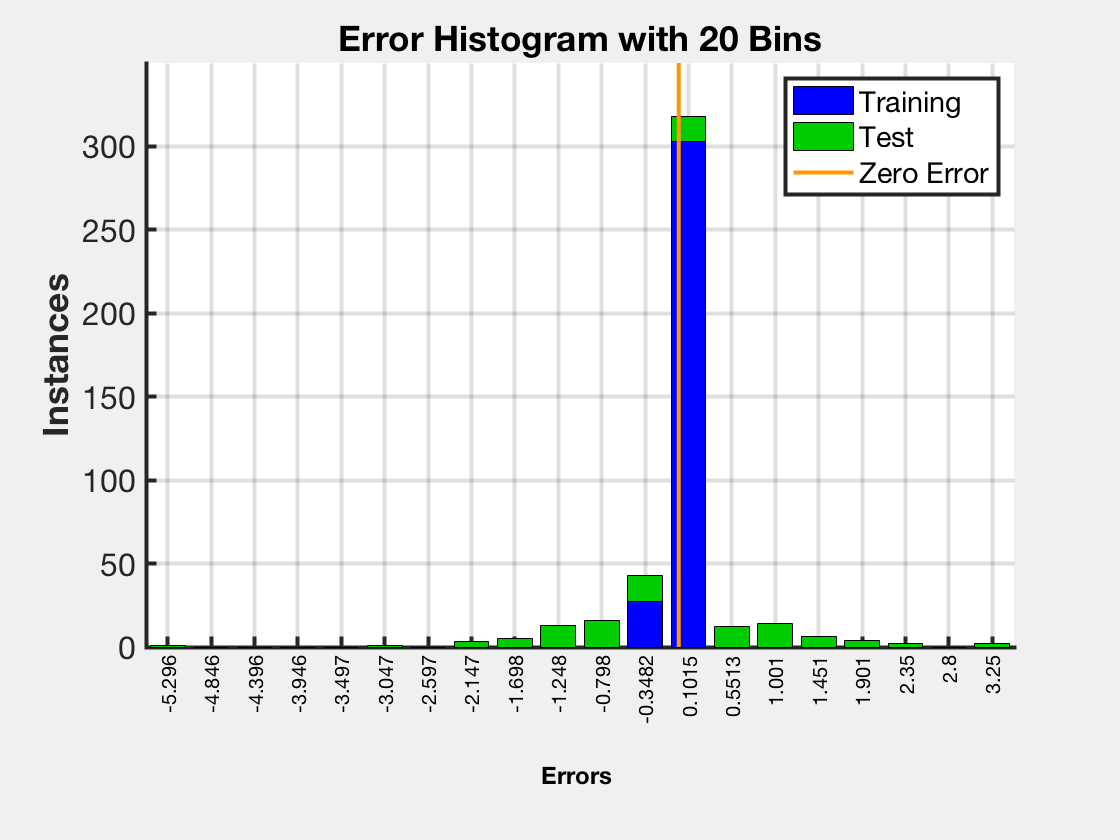

% plot error histogram
plotErrorHistogram(nc_train_output, outputs_en_train, nc_test_output, outputs_en_test)

%--------------------------------------------------------------------------
% calculate the mean square error (MSE) of the test points
mse_train=sum((outputs_en_train - nc_train_output).^2)/length(nc_train_output);
mse_test=sum((outputs_en_test - nc_test_output).^2)/length(nc_test_output);

%--------------------------------------------------------------------------
% calculate the correlation coefficients for the training and test data 
% sets with the associated linear fits hint: check out the function corrcoef
R_train = corrcoef(outputs_en_train,nc_train_output);
R_test = corrcoef(outputs_en_test,nc_test_output);
r_train=R_train(1,2);
r_test=R_test(1,2);

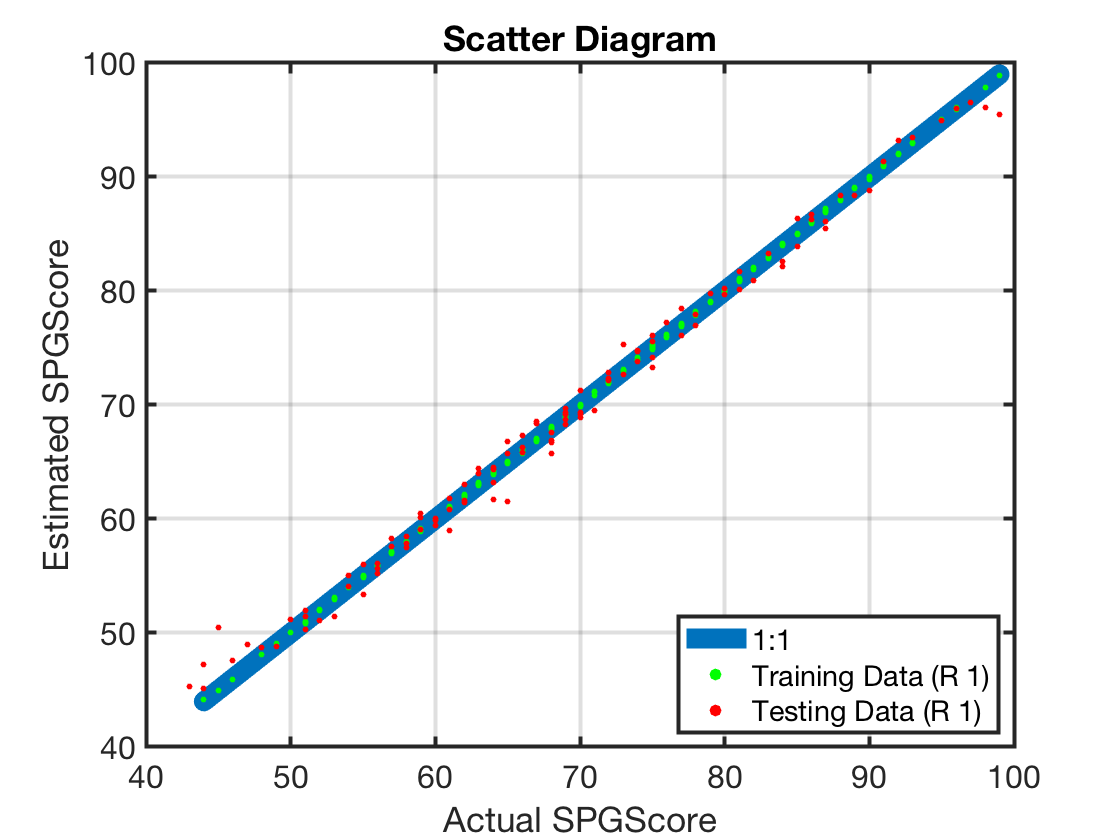

% plot scatter plot
plotScatterDiagram(nc_train_output, outputs_en_train, nc_test_output, outputs_en_test, r_train, r_test)

%--------------------------------------------------------------------------
% Estimate the predictor importance
imp=predictorImportance(Mdl_en)

imp =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000         0    0.0000    0.0000         0         0         0    0.0002    0.0000    0.0206    0.6293    0.0010    0.0001    0.0011    0.0002         0    0.0000    0.0000    0.0000    0.0000         0    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000         0    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000         0    0.0002


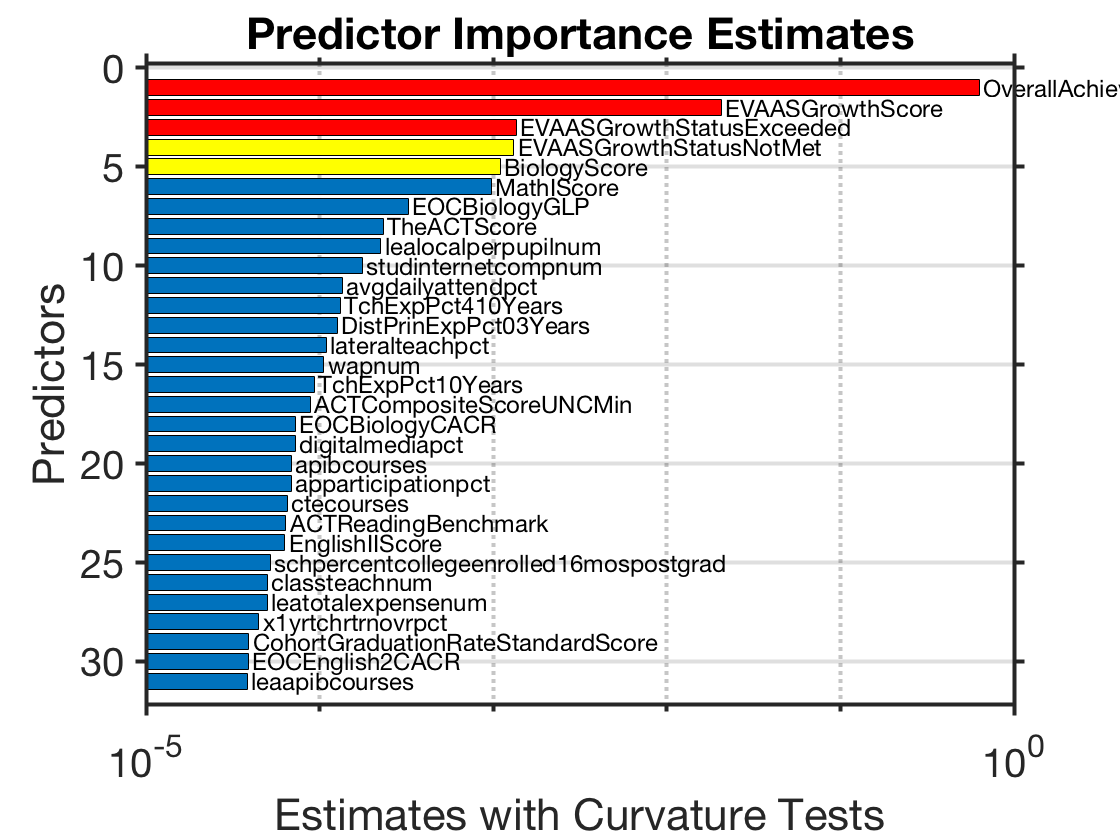

[sorted_imp,isorted_imp] = sort(imp,'descend');  

n = sum(imp>0);
if n  > 31
    n = 31;
end

%--------------------------------------------------------------------------
% Draw a horizontal bar chart showing the variables in descending order of
% importance. Hint: look up the function barh.
% Label each variable with its name. 
% Hints: (1) Look up the function text. (2) Variable names are held in 
% Mdl.PredictorNames
figure;barh(imp(isorted_imp(1:n)));hold on;grid on;
barh(imp(isorted_imp(1:5)),'y');barh(imp(isorted_imp(1:3)),'r');
title('Predictor Importance Estimates');
xlabel('Estimates with Curvature Tests');ylabel('Predictors');
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
ax = gca;ax.YDir='reverse';ax.XScale = 'log';

sorted_predictor_names = Mdl_en.PredictorNames(isorted_imp(1:n));

% label the bars
for i=1:length(sorted_predictor_names)
   text(...
        1.05*imp(isorted_imp(i)),i,...
        strrep(sorted_predictor_names{i},'_',''),...
        'FontSize',12 ...
    )
end
print('-dpng','NC-full-input-importance.png');% save to an png file

for col=sorted_predictor_names
disp(col)
end

    'OverallAchievementScore'

    'EVAASGrowthScore'

    'EVAASGrowthStatus_Exceeded'

    'EVAASGrowthStatus_NotMet'

    'BiologyScore'

    'MathIScore'

    'EOC_Biology_GLP'

    'TheACTScore'

    'lea_local_perpupil_num'

    'stud_internet_comp_num'

    'avg_daily_attend_pct'

    'Tch_Exp_Pct_4_10_Years'

    'Dist_Prin_Exp_Pct_0_3_Years'

    'lateral_teach_pct'

    'wap_num'

    'Tch_Exp_Pct_10__Years'

    'ACT_Composite_Score_UNC_Min'

    'EOC_Biology_CACR'

    'digital_media_pct'

    'ap_ib_courses'

    'ap_participation_pct'

    'cte_courses'

    'ACT_Reading_Benchmark'

    'EnglishIIScore'

    'sch_percent_college_enrolled_16_mos_post_grad'

    'class_teach_num'

    'lea_total_expense_num'

    'x_1yr_tchr_trnovr_pct'

    'CohortGraduationRateStandardScore'

    'EOC_English_2_CACR'

    'lea_ap_ib_courses'



# Ensemble Model Regression with simpler model

% Model using the best predictors
nc_train_input_simpler = nc_train_input(:, isorted_imp(1:n));
nc_test_input_simpler = nc_test_input(:, isorted_imp(1:n));

% set random seed.
rng(1);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
Copying objective function to workers...
Done copying objective function to workers.


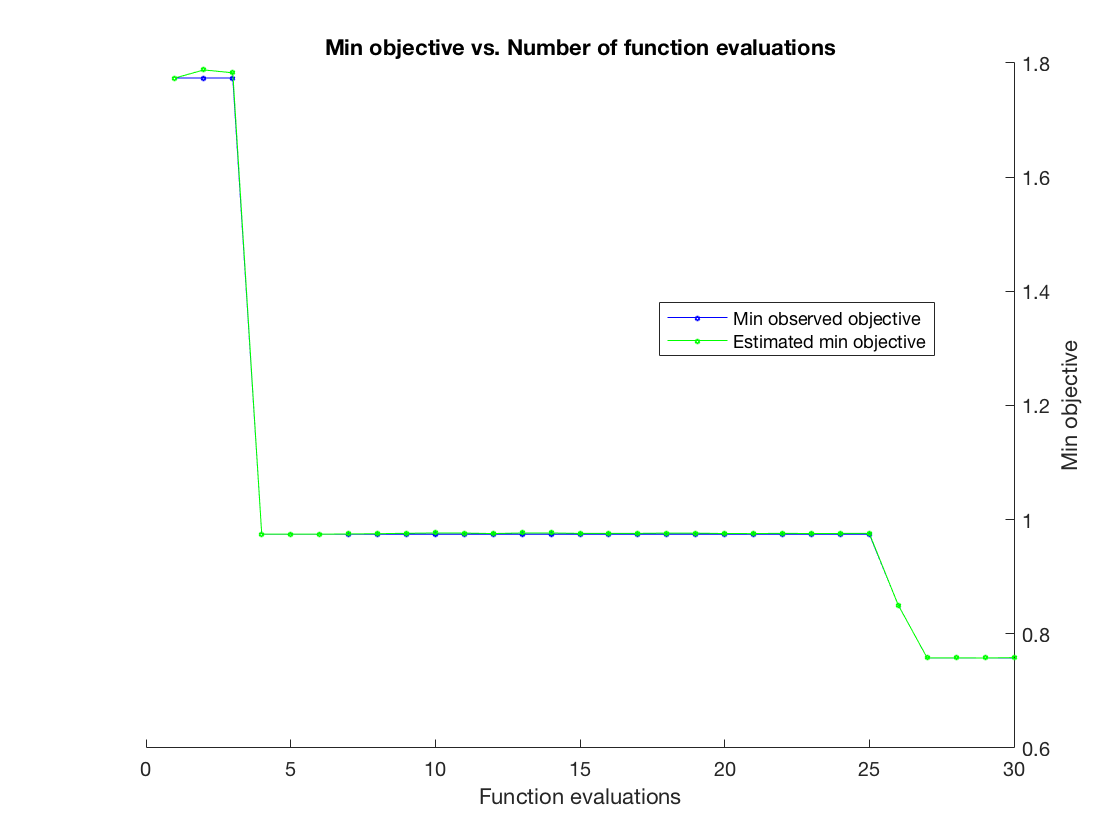

|===========================================================================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize | MaxNumSplits | NumVariables-|
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |              | ToSample     |
|===========================================================================================================================================================================|
|    1 |       2 | Best   |      1.7737 |      29.783 |      1.7737 |      1.7737 |          Bag |          134 |            - |            1 |           88 |           11 |
|    2 |       2 | Accept |      1.9479 |      41.618 |      1.7737 |      1.7879 |      LSBoost |          253 |     0.059517 |  

Mdl_en_simpler =   classreg.learning.regr.RegressionEnsemble
                       PredictorNames: {1×31 cell}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 330
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 54
                               Method: 'LSBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [54×1 double]
                   FitInfoDescription: {2×1 cell}
                       Regularization: []


  Properties, Method

%--------------------------------------------------------------------------
% Create ensemble model with Hyperparameter Optimization
Mdl_en_simpler = fitrensemble(...
    nc_train_input_simpler,nc_train_output,...
    'OptimizeHyperparameters','all', ...
    'HyperparameterOptimizationOptions',struct('UseParallel',true,'ShowPlots',true) ...
    )

% predict
outputs_en_train_simpler=predict(Mdl_en_simpler, nc_train_input_simpler);
outputs_en_test_simpler=predict(Mdl_en_simpler,nc_test_input_simpler);

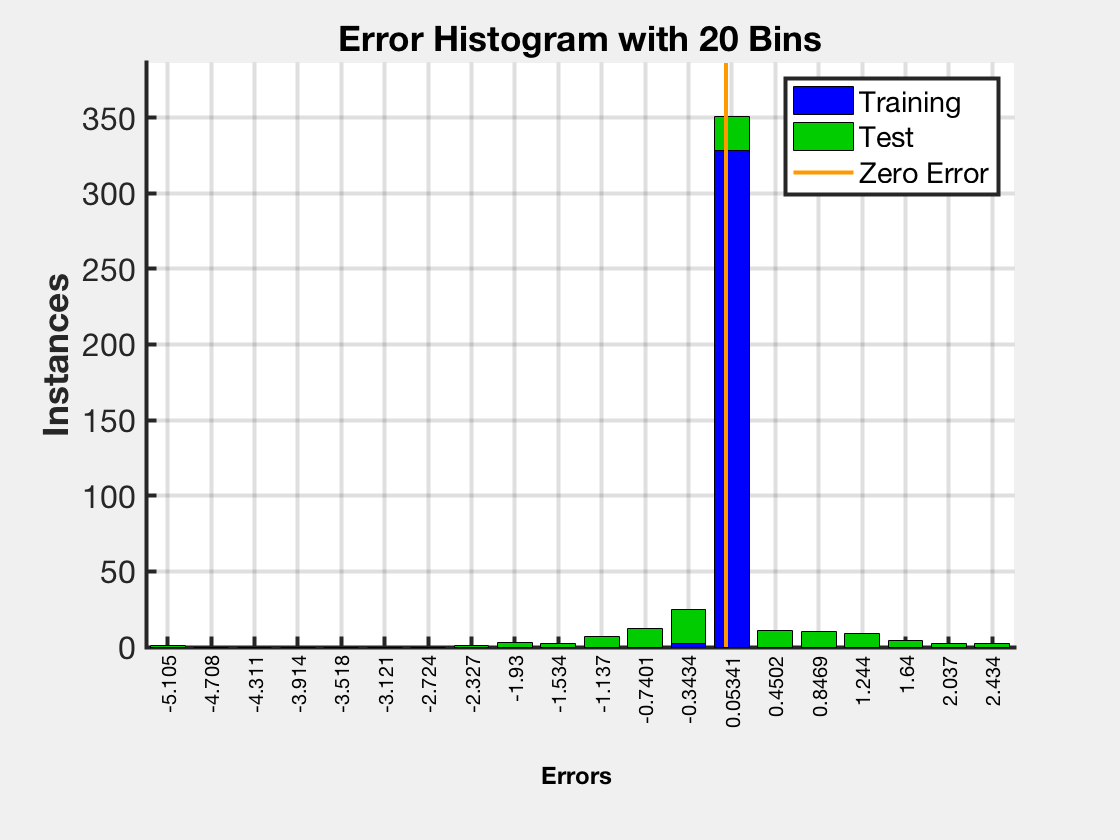

% plot error histogram
plotErrorHistogram(nc_train_output, outputs_en_train_simpler, nc_test_output, outputs_en_test_simpler)

%--------------------------------------------------------------------------
% calculate the mean square error (MSE) of the test points
mse_train=sum((outputs_en_train_simpler - nc_train_output).^2)/length(nc_train_output);
mse_test=sum((outputs_en_test_simpler - nc_test_output).^2)/length(nc_test_output);

%--------------------------------------------------------------------------
% calculate the correlation coefficients for the training and test data 
% sets with the associated linear fits hint: check out the function corrcoef
R_train = corrcoef(outputs_en_train_simpler,nc_train_output);
R_test = corrcoef(outputs_en_test_simpler,nc_test_output);
r_train=R_train(1,2);
r_test=R_test(1,2);

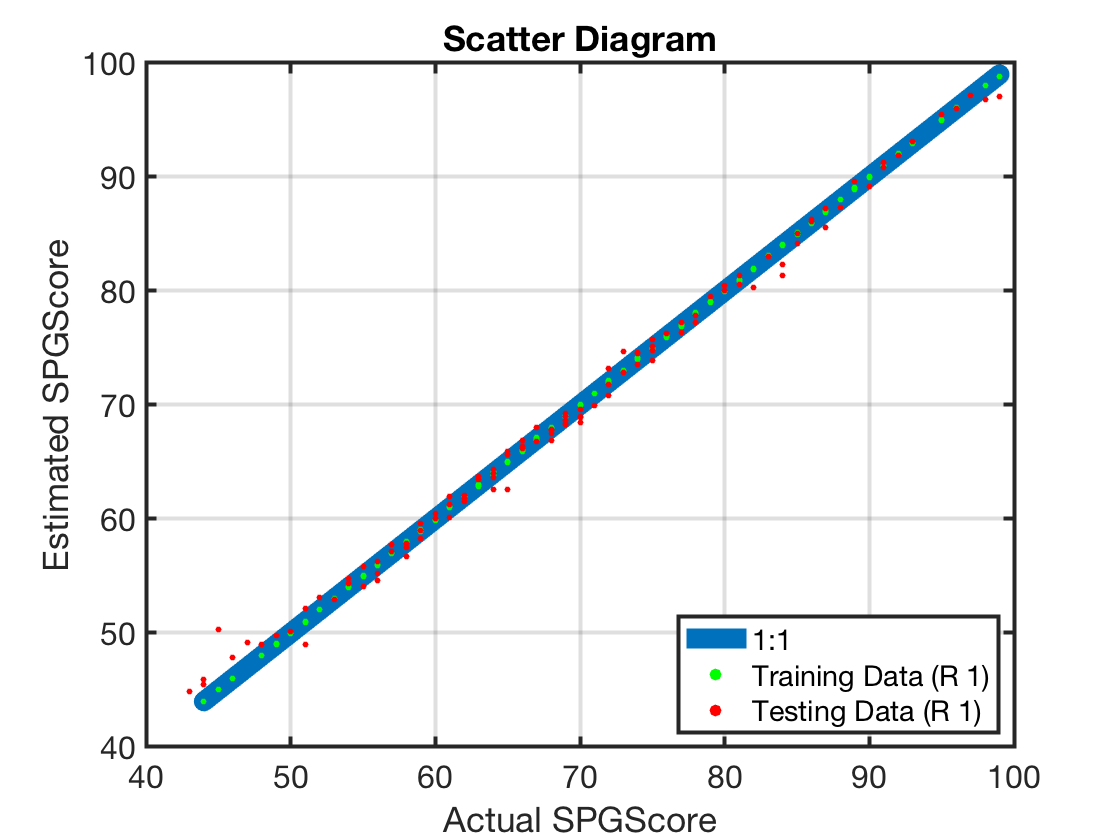

% plot scatter plot
plotScatterDiagram(nc_train_output, outputs_en_train_simpler, nc_test_output, outputs_en_test_simpler, r_train, r_test)

# Neural Network Regression using Ensemble Boosting algorithm's best predictors.

% save the variables
% save AllRegressionLearners
% ml_data_simple_en = ml_data(:, isorted_imp(1:n));
% save Ensemble_Regression_Simple.mat ml_data_simple_en

Prepare data for sending it into a neural network

% Commands to create Ensemble Neural Network data with simple model
clear;  close all; clc;
load Ensemble_Regression_Simple.mat
target = ml_data_output;
X_EN = ml_data_simple_en{:,:};
X_EN = X_EN';
Y_EN = target;
Y_EN = Y_EN';
save nn_reg_en.mat X_EN Y_EN;

run('en_reg_nn.m')

# Performance of th best Neural Network Architecture using Ensemble Boosting Regressor's best predictors

run('en_reg_nn_best.m')

# Neural Network Regression using TreeBagger algorithm's best predictors.

%ml_data_simple_tb = ml_data(:, isorted_imp(1:n));
%save TreeBagger_Regression_Simple.mat ml_data_simple_tb

Mean Squared Error for nn_10 is: 2.205103
Mean Squared Error for nn_20 is: 2.503250
Mean Squared Error for nn_20_20 is: 3.123663
Mean Squared Error for nn_20_20_20 is: 2.644605
Mean Squared Error for nn_50 is: 2.754724
Mean Squared Error for nn_50_50 is: 5.583735
Mean Squared Error for nn_100 is: 82.732977
Mean Squared Error for nn_100_20 is: 1.621472


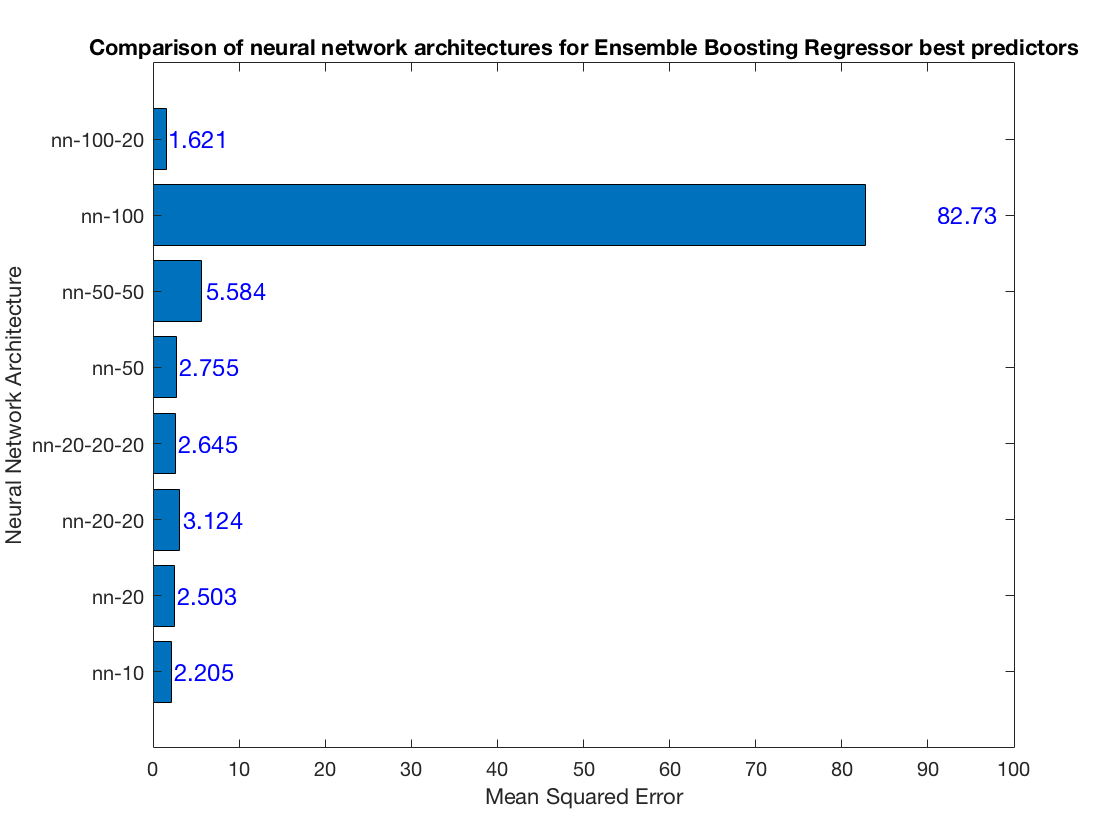

% Commands to create Ensemble Neural Network data with simple model

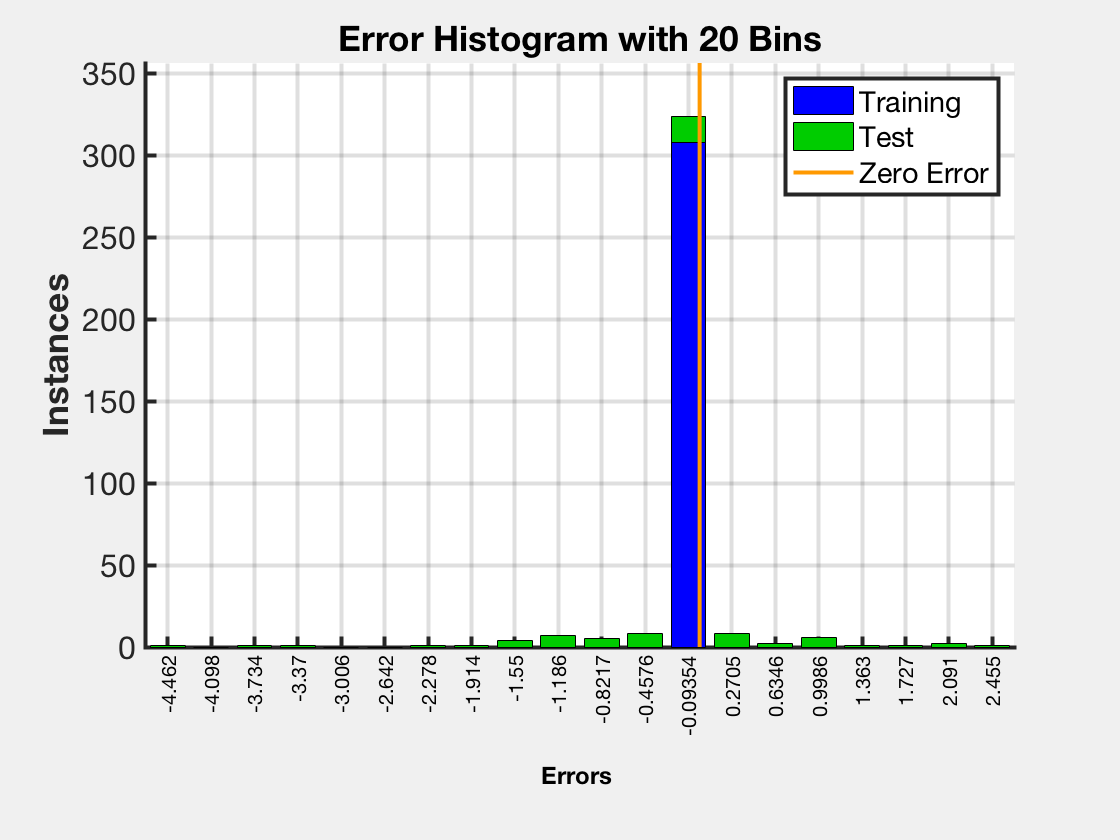

R_train =     1.0000    1.0000
    1.0000    1.0000


R_test =     1.0000    0.9954
    0.9954    1.0000


r_train = 1.0000

r_test = 0.9954

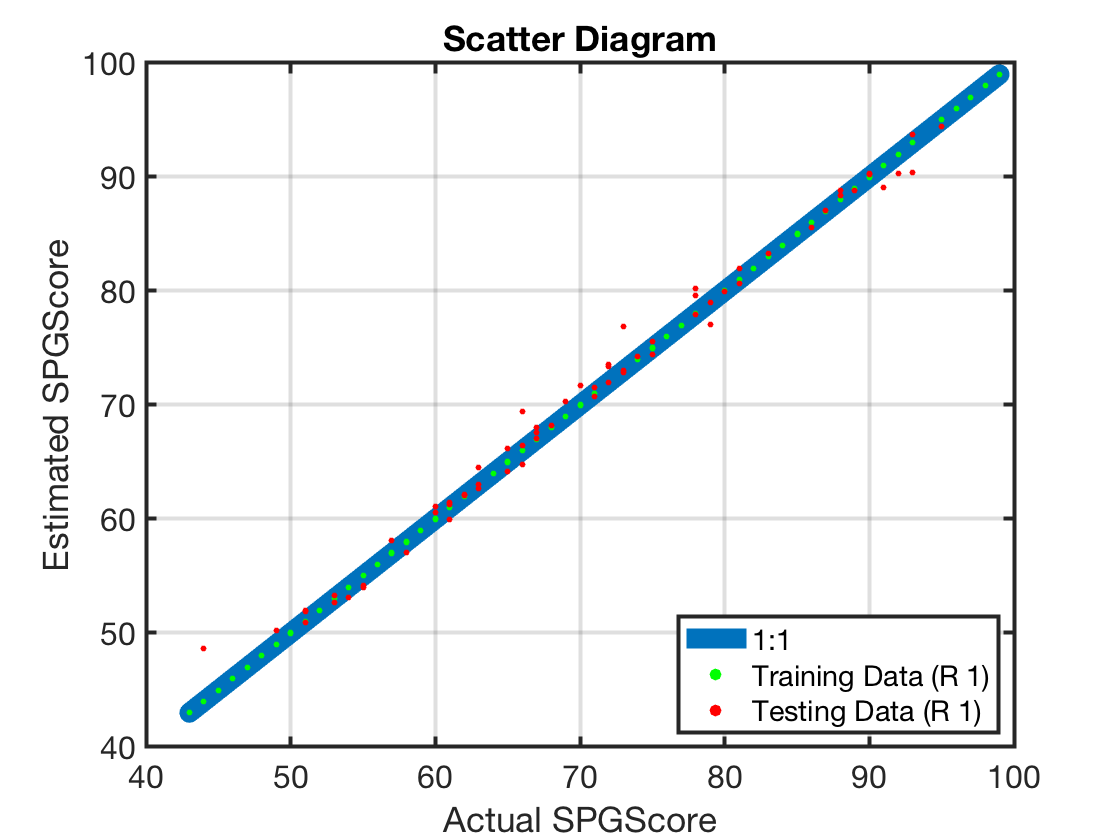

meanSqErr = 1.6215

Mean Squared Error for nn_100_20 is: 1.621472


clear; close all; clc;
load TreeBagger_Regression_Simple.mat;
target = ml_data_output;
X_TB = ml_data_simple_tb{:,:};
X_TB = X_TB';

Y_TB = target;
Y_TB = Y_TB';
save nn_reg_tb.mat X_TB Y_TB;

run('tb_reg_nn.m')

# Performance of th best Neural Network Architecture using TreeBagger Regressor's best predictors

Mean Squared Error for nn_10 is: 0.445942
Mean Squared Error for nn_20 is: 1.543293
Mean Squared Error for nn_20_20 is: 1.431745
Mean Squared Error for nn_20_20_20 is: 1.587794
Mean Squared Error for nn_50 is: 2.146929
Mean Squared Error for nn_50_50 is: 6.722760
Mean Squared Error for nn_100 is: 25.879183
Mean Squared Error for nn_100_20 is: 2.180521


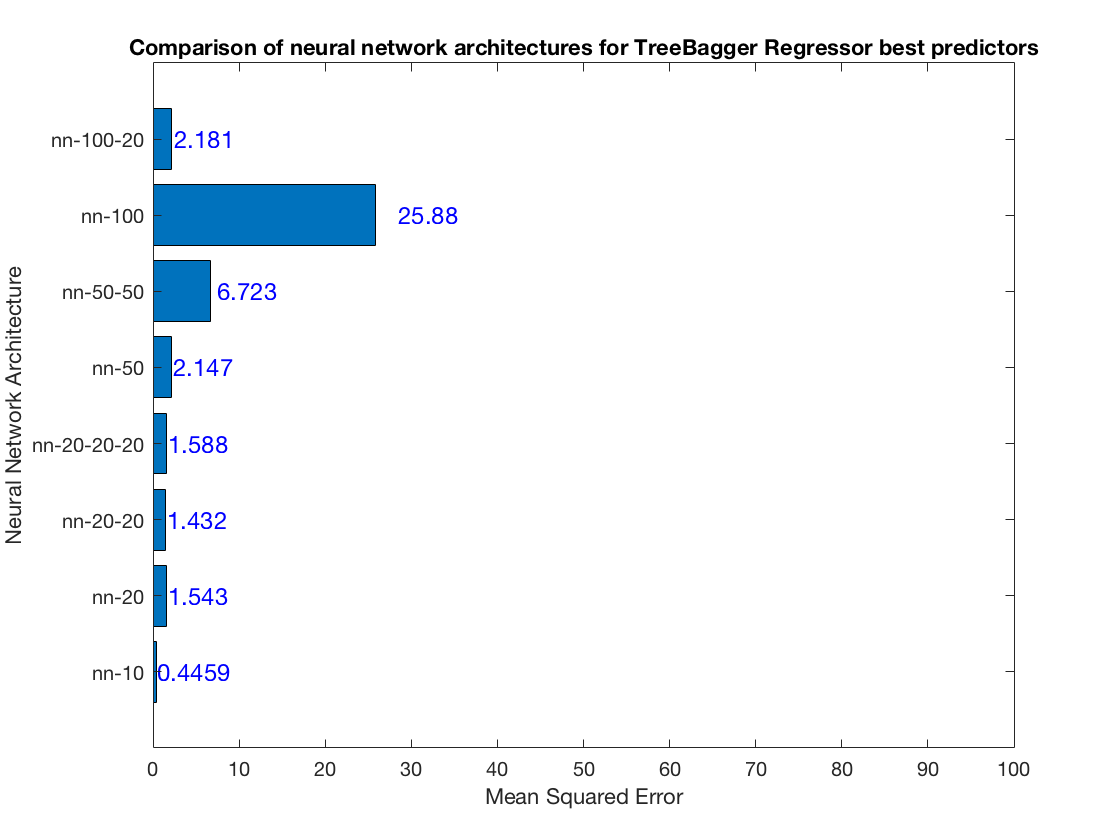

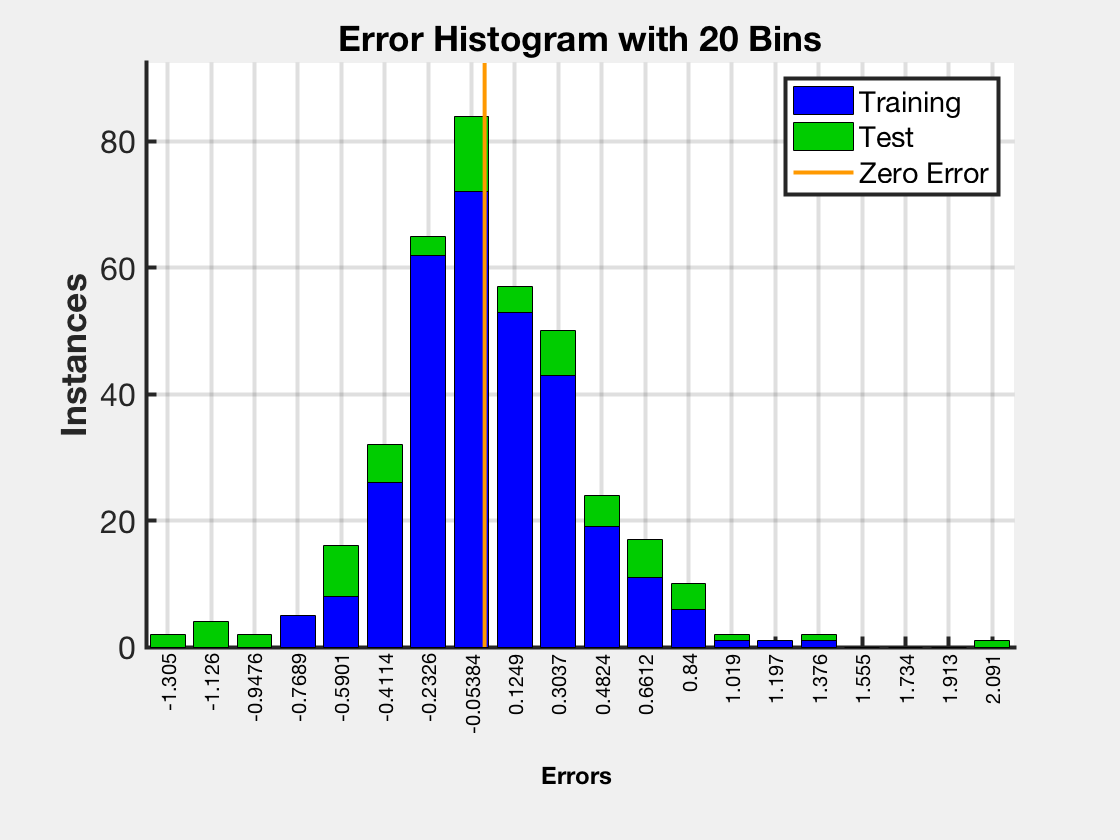

R_train =     1.0000    0.9997
    0.9997    1.0000


R_test =     1.0000    0.9984
    0.9984    1.0000


r_train = 0.9997

r_test = 0.9984

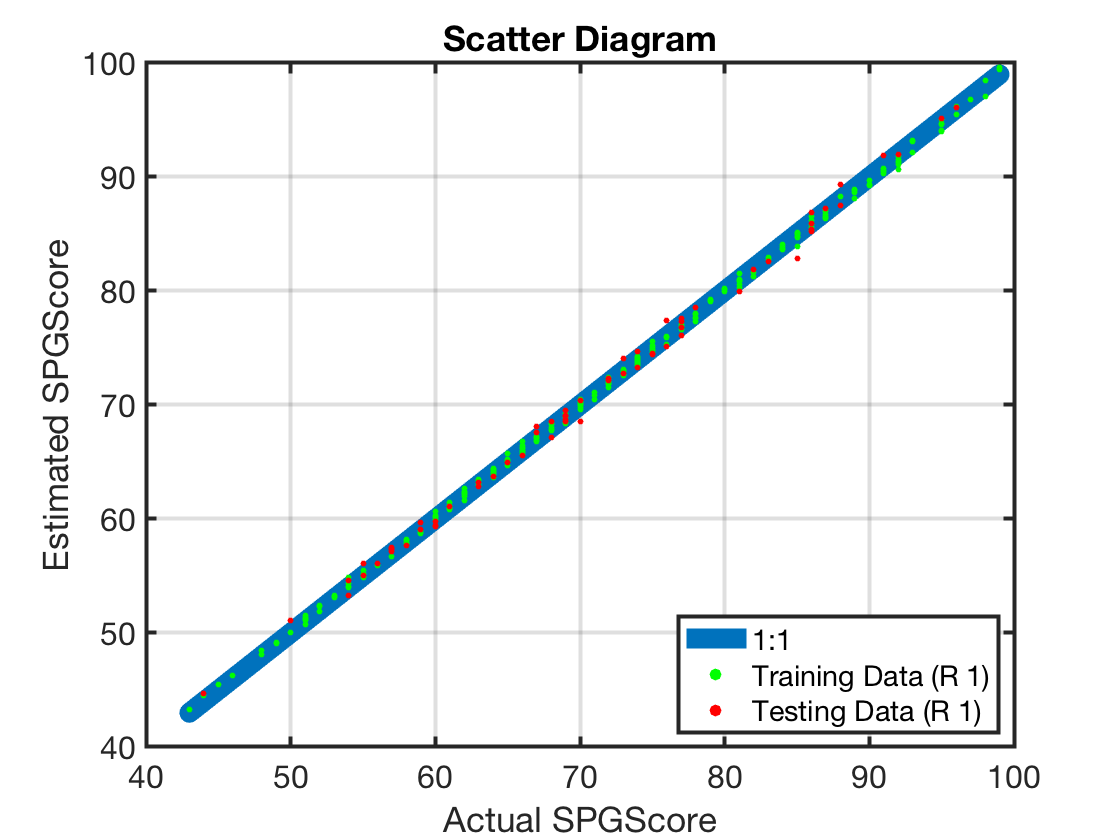

meanSqErr = 0.4459

Mean Squared Error for nn_10 is: 0.445942


run('tb_reg_nn_best.m')

# Conclusion

•Educators, State/School officials can examine these features and recommend areas of improvement to schools.

•Important to study the feature importance over the years, a key question to answer in the coming years: do the same features appear each year or do new features play an important role in differentiating these schools ?